% CVD Simulation code with extra comments for external use
% Original code created: 3/10/21
% Last updated: 4/03/25
% File Name: CVD_Simulation.mlx

clear;
close all;


## Establish Core Variables

% Load image 

Img_RGB = uigetfile({'*.png;*.jpg;*.tif;*.jpeg'});
Img_RGB = imread(Img_RGB);

% Load in sRGB Display Primaries (with or without color correcting glasses)

Color_Correcting_Glasses = false;

if Color_Correcting_Glasses == true
    iPhone_Primaries = readmatrix('iPhone5_Notch_Primaries.xlsx', 'Range', 'B2:D62');
    D65_Spectrum = readmatrix('iPhone5_Notch_Primaries.xlsx', 'Range', 'F2:F62');
else
    iPhone_Primaries = readmatrix('iPhone5_sRGB_Primaries.xlsx', 'Range', 'B2:D62');
    D65_Spectrum = readmatrix('iPhone5_sRGB_Primaries.xlsx', 'Range', 'F2:F62');
end

% Define Color Vision Deficiency

Deuteranomalous = true;

separation = 0;    % spectral separation of 0 = dichromat
                                            % max spectral separation = 12nm

Tritan = false;  % check box to simulate Tritanopia

% Define photopigment peaks and optical densities

photopeaks = zeros(1,2);

if Tritan == true
    photopeaks(1) = 530;
    photopeaks(2) = 557.25;
    opticald(1) = 0.22;
    opticald(2) = 0.35;
elseif exist('Protanomalous', 'var')
    photopeaks(1) = 530;
    photopeaks(2) = photopeaks(1)+separation;
    opticald(1) = 0.22;
    opticald(2) = ((photopeaks(2)-photopeaks(1))*0.005)+opticald(1);
elseif exist('Deuteranomalous', 'var')
    photopeaks(2) = 557.25;
    photopeaks(1) = photopeaks(2)-separation;
    opticald(2)=0.35;
    opticald(1) = opticald(2)-((photopeaks(2)-photopeaks(1))*0.005);
end

if Tritan == true
    Deutan = false;
    Protan = false;
    Anomalous = false;
elseif photopeaks(1) == 557.25
    Deutan = true;
    Protan = false;
    Anomalous = false;
elseif photopeaks(2) == 530
    Protan = true;
    Deutan = false;
    Anomalous = false;
else
    Deutan = false;
    Protan = false;
    Anomalous = true;
end


## Spectral Sensitivity Calculation

% Calculate quantal spectral sensitivity for normal L and M cones using Spec function

wavelengths = 400:1:700;

age = 35;     % age = 0 uses Stockman Lens and Macular Pigment.
                                    % Any other number uses the Dirk van Norren equation.

normal_peaks=[419, 530, 557.25];    % Typical S, M, and L photopigment peaks
normal_od=[0.4, 0.22, 0.34];        % Typical S, M, and L photopigment optical densities

if age == 0
    normal_S = neitzSpec(normal_peaks(1), ...
                         normal_od(1), ...
                         wavelengths, ...
                         'lensod', 'stockman', ...
                         'units', 'energy');

    normal_M = neitzSpec(normal_peaks(2), ...
                         normal_od(2), ...
                         wavelengths, ...
                         'lensod', 'stockman', ...
                         'units', 'energy');

    normal_L = neitzSpec(normal_peaks(3), ...
                         normal_od(3), ...
                         wavelengths, ...
                         'lensod', 'stockman', ...
                         'units', 'energy');
else
    normal_S = neitzSpec(normal_peaks(1), ...
                         normal_od(1), ...
                         wavelengths, ...
                         'age', age, ...
                         'lensod', 'vanNorren', ...
                         'units', 'energy');

    normal_M = neitzSpec(normal_peaks(2), ...
                         normal_od(2), ...
                         wavelengths, ...
                         'age', age, ...
                         'lensod', 'vanNorren', ...
                         'units', 'energy');

    normal_L = neitzSpec(normal_peaks(3), ...
                         normal_od(3), ...
                         wavelengths, ...
                         'age', age, ...
                         'lensod', 'vanNorren', ...
                         'units', 'energy');
end

% Calculate spectral sensitivity of anomalous cones using Spec function

if age == 0
    anomalous_M = neitzSpec(photopeaks(1), ...
                            opticald(1), ...
                            wavelengths, ...
                            'lensod', 'stockman', ...
                            'units', 'energy');

    anomalous_L = neitzSpec(photopeaks(2), ...
                            opticald(2), ...
                            wavelengths, ...
                            'lensod', 'stockman', ...
                            'units', 'energy');
else
    anomalous_M = neitzSpec(photopeaks(1), ...
                            opticald(1), ...
                            wavelengths, ...
                            'age', age, ...
                            'lensod', 'vanNorren', ...
                            'units', 'energy');

    anomalous_L = neitzSpec(photopeaks(2), ...
                            opticald(2), ...
                            wavelengths, ...
                            'age', age, ...
                            'lensod', 'vanNorren', ...
                            'units', 'energy');
end


## Anomaloscope Calculation

% Use anomaloscope function to calculate rayleigh match, rayleigh range,
% and percent color loss (if anomalous)

[RG_Match, Y_Match, Rayleigh_Range, loss]=anomaloscope(normal_L, ...
                                                       normal_M, ...
                                                       anomalous_L, ...
                                                       anomalous_M);

if Anomalous == true
    disp(['The Rayleigh match is ', num2str(RG_Match), ' at a Yellow setting of ', num2str(Y_Match)])
    disp(['The Rayleigh range is ', num2str(Rayleigh_Range)])
    disp(['Color vision loss is ', num2str(loss*100), ' percent.'])
elseif Protan == true
    disp('The subject is a protanope.')
elseif Deutan == true
    disp('The subject is a deuteranope.')
end

The subject is a deuteranope.


## V Lambda Calculation

% Derive appropriate V Lambda based on cones and color vision deficiency

LM_Ratio = 2; % Choose L/M ratio, default is 2:1

if Tritan == true
    V_Lambda = LM_Ratio*normal_L+normal_M;
elseif Deutan == true
    V_Lambda = normal_L;
elseif Protan == true
    V_Lambda = normal_M;
elseif Anomalous == true
    V_Lambda = LM_Ratio*anomalous_L+anomalous_M;
end

V_Lambda = V_Lambda/max(V_Lambda);


## Tristimulus Calculation

% Use tristimulus function to derive LMS to CIERGB matrix, CIERGB to CIEXYZ matrix,
% and Tristimulus values

[Tristimulus, LMS_to_RGB, RGB_to_XYZ] = tristimulus(normal_L, ...
                                                    normal_M, ...
                                                    normal_S, ...
                                                    V_Lambda);


## Color Conversion Matrix Calculation

% Use colorconversions function to derive sRGB to LMS matrix

sRGB_to_LMS = colorconversions(Tristimulus, ...
                               LMS_to_RGB, ...
                               RGB_to_XYZ, ...
                               iPhone_Primaries, ...
                               D65_Spectrum);


## Image Transformations

% Gamma correction and display before image

disp("Before Conversion:")

Before Conversion:


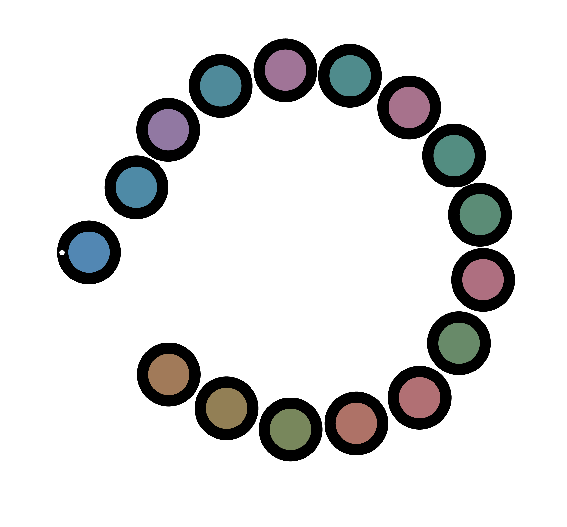

beforeImage = figure;
Img_RGB_gamma = im2double(Img_RGB).^2.2;        % apply gamma correction
imshow(Img_RGB)                                 % show "normal" version of image

After Conversion:


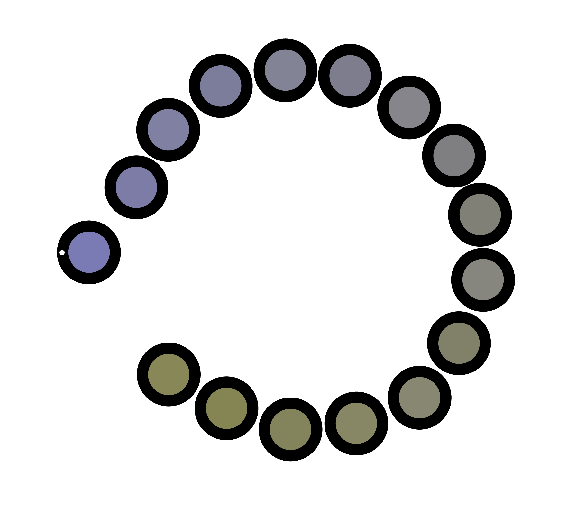


% Permute and reshape RGB values

X = size(Img_RGB_gamma,1);
Y = size(Img_RGB_gamma,2);

Img_Reshape = permute(Img_RGB_gamma, [3,1,2]);
Img_Reshape = reshape(Img_Reshape, 3, X*Y);

% Transform RGB values in image to LMS values

Img_LMS = sRGB_to_LMS*Img_Reshape;

% Calculate variables for reduced plane equation

LMS_w = sRGB_to_LMS*[1;1;1];
LMS_b = sRGB_to_LMS*[0;0;1];
LMS_g = sRGB_to_LMS*[0;1;0];
LMS_r = sRGB_to_LMS*[1;0;0];
alpha = (LMS_w(2)*LMS_b(3)) - (LMS_b(2)*LMS_w(3));
beta = (LMS_w(3)*LMS_b(1)) - (LMS_b(3)*LMS_w(1));
gamma = (LMS_w(1)*LMS_b(2)) - (LMS_b(1)*LMS_w(2));

if Tritan == true
    alpha_t = (LMS_r(2)*LMS_w(3)) - (LMS_w(2)*LMS_r(3));
    beta_t = (LMS_w(1)*LMS_r(3)) - (LMS_r(1)*LMS_w(3));
    gamma_t = (LMS_w(2)*LMS_r(1)) - (LMS_r(2)*LMS_w(1));
end

% NOTE: To save the output from these transformations, uncomment the
% imwrite() and imagename lines below.

% Deutan Transform

if Deutan == true
    Deutan = figure('Name','Deuteranope', 'NumberTitle', 'off');
    D_matrix = [1, 0, 0 ; -alpha/beta, 0, -gamma/beta; 0, 0, 1];
    Img_D = D_matrix*Img_LMS;
    Img_D_RGB = inv(sRGB_to_LMS)*Img_D; %#ok<*MINV> 
    D_Nope = reshape(Img_D_RGB, 3, X, Y);
    D_Nope = permute(D_Nope, [2,3,1]);
    D_Nope = D_Nope.^(1/2.2);
    D_Nope = uint8(D_Nope.*255);
    disp("After Conversion:")
    imshow(real(D_Nope));
    %imwrite(real(D_Nope), 'Dnope.jpg', 'Quality', 100);
end


% Protan Transform

if Protan == true
    Protan = figure('Name','Protanope', 'NumberTitle', 'off');
    P_matrix = [0, -beta/alpha, -gamma/alpha; 0, 1, 0; 0, 0, 1];
    Img_P = P_matrix*Img_LMS;
    Img_P_RGB = inv(sRGB_to_LMS)*Img_P;
    P_Nope = reshape(Img_P_RGB, 3, X, Y);
    P_Nope = permute(P_Nope, [2,3,1]);
    P_Nope = P_Nope.^(1/2.2);
    P_Nope = uint8(P_Nope.*255);
    disp("After Conversion:")
    imshow(real(P_Nope));
    %imwrite(real(P_Nope), 'Pnope.jpg', 'Quality', 100);
end

% Tritan Transform 
if Tritan == true
    Tritan = figure('Name','Tritanope', 'NumberTitle', 'off');
    T_matrix = [1,0,0; 0,1,0; -alpha_t/gamma_t, -beta_t/gamma_t, 0];
    Img_T = T_matrix*Img_LMS;
    Img_T_RGB = inv(sRGB_to_LMS)*Img_T;
    T_Nope = reshape(Img_T_RGB, 3, X, Y);
    T_Nope = permute(T_Nope, [2,3,1]);
    T_Nope = T_Nope.^(1/2.2);
    T_Nope = uint8(T_Nope.*255);
    disp("After Conversion:")
    imshow(real(T_Nope));
    %imwrite(real(T_Nope), 'Tnope.jpg', 'Quality', 100);
end

% Deuteranomalous Transform

if exist('Deuteranomalous', 'var') && Deutan == false && Tritan == false

    D_matrix = [1, 0, 0 ; -alpha/beta, 0, -gamma/beta; 0, 0, 1];
    Img_D = D_matrix*Img_LMS;
    distance_D = Img_LMS - Img_D;
    distance_D = distance_D(2,:);
    
    percent_D = rescale(distance_D);
    
    Deuteranomalous = figure('Name', 'Deuteranomalous', 'NumberTitle','off');
    Img_DA = zeros(size(Img_D));
    
    for x = 1:length(percent_D)
        Img_DA(2,x) = Img_LMS(2,x)-(distance_D(x)*loss);
        Img_DA(1,x) = Img_LMS(1,x);
        Img_DA(3,x) = Img_LMS(3,x);
    end
    
    Img_DA_RGB = inv(sRGB_to_LMS)*Img_DA;
    D_Ano = reshape(Img_DA_RGB, 3, X, Y);
    D_Ano = permute(D_Ano, [2,3,1]);
    D_Ano = D_Ano.^(1/2.2);
    D_Ano = uint8(D_Ano.*255);
    disp("After Conversion:")
    imshow(real(D_Ano));
    % imagename = ['DA_', num2str(separation), '.jpg'];
    % imwrite(real(D_Ano), imagename, 'Quality', 100);
    
% Protanomalous Transform

elseif exist('Protanomalous','var') && Protan == false && Tritan == false

    P_matrix = [0, -beta/alpha, -gamma/alpha; 0, 1, 0; 0, 0, 1];
    Img_P = P_matrix*Img_LMS;
    distance_P = Img_LMS - Img_P;
    distance_P = distance_P(1,:);
    
    percent_P = rescale(distance_P);
    
    Protanomalous = figure('Name', 'Protanomalous', 'NumberTitle', 'off');
    Img_PA = zeros(size(Img_P));
    
    for x = 1:length(percent_P)
        Img_PA(1,x) = Img_LMS(1,x)-(distance_P(x)*loss);
        Img_PA(2,x) = Img_LMS(2,x);
        Img_PA(3,x) = Img_LMS(3,x);
    end
    
    Img_PA_RGB = inv(sRGB_to_LMS)*Img_PA;
    P_Ano = reshape(Img_PA_RGB, 3, X, Y);
    P_Ano = permute(P_Ano, [2,3,1]);
    P_Ano = P_Ano.^(1/2.2);
    P_Ano = uint8(P_Ano.*255);
    disp("After Conversion:")
    imshow(real(P_Ano));
    % imagename = ['PA_', num2str(separation), '.jpg'];
    % imwrite(real(P_Ano), imagename, 'Quality', 100);

end